% question 1 
% read input data table using a column format string %u = integer, %f =
% floating point (decimal) 
% T = readtable(filename,'Format','%s%s%u%f%f%s')
INTEMP = readtable('GlobalTempbyYear.txt','Format','%u%f%f%f%f%f%f%f%f%f%f%f')

INTEMP = 169×12 table
    Var1     Var2      Var3      Var4      Var5      Var6      Var7      Var8      Var9     Var10     Var11     Var12 
    ____    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    1850    -0.373    -0.425    -0.339    -0.502    -0.243    -0.536     -0.21    -0.515    -0.238    -0.591    -0.162
    1851    -0.218    -0.274    -0.184     -0.35    -0.086    -0.368    -0.068    -0.365    -0.081    -0.429    -0.016
    1852    -0.228     -0.28    -0.196    -0.353    -0.103    -0.378    -0.078    -0.367    -

% detected line spacing by using opts function 
% opts = detectImportOptions('GlobalTempbyYear.txt')
%{ 
readtable('patients.xls',...
    'Range','C2:E6',...
    'ReadVariableNames',false)
%}

INCARB = readtable ('GlobalCarbonBudget2018.xlsx', ...
    'Range','A15:G283', ...
    'Sheet',"Historical Budget")

INCARB = 268×7 table
    Year    fossilFuelAndIndustry    land_useChangeEmissions    atmosphericGrowth    oceanSink    landSink     budgetImbalance
    ____    _____________________    _______________________    _________________    _________    _________    _______________

    1750              NaN                      NaN                  -0.077592           NaN        0.089932          NaN      
    1751            0.003                      NaN                  -0.073988           NaN        -0.52998          NaN      
    1752            0.003                      NaN                  -0.070596           NaN        -0.26549          NaN      
    1753            0.003                      NaN                  -0.067628           NaN        -0.165

GCARB = INCARB(101:end,:)

GCARB = 168×7 table
    Year    fossilFuelAndIndustry    land_useChangeEmissions    atmosphericGrowth    oceanSink    landSink     budgetImbalance
    ____    _____________________    _______________________    _________________    _________    _________    _______________

    1850            0.054                    0.68781                  0.18868          0.1642       0.56153       -0.17259    
    1851            0.054                    0.69178                   0.1255         0.16548     -0.016708         0.4715    
    1852            0.057                    0.69671                 0.069536         0.17164       0.26513         0.2474    
    1853            0.059                     0.7019                  0.00954         0.17291      0.08062

GTEMP = INTEMP(:,[1 2])

GTEMP = 169×2 table
    Var1     Var2 
    ____    ______

    1850    -0.373
    1851    -0.218
    1852    -0.228
    1853    -0.269
    1854    -0.248
    1855    -0.272
    1856    -0.358
    1857    -0.461
    1858    -0.467
    1859    -0.284
    1860    -0.343
    1861    -0.407
    1862    -0.524
    1863    -0.278
    1864    -0.494
    1865    -0.279


% question 2 
% get the cumsum input as a matrix with the two columns from GCARB 
A = GCARB{:, [ "fossilFuelAndIndustry","land_useChangeEmissions"]}

A =     0.0540    0.6878
    0.0540    0.6918
    0.0570    0.6967
    0.0590    0.7019
    0.0690    0.7047
    0.0710    0.7067
    0.0760    0.7108
    0.0770    0.7174
    0.0780    0.7229
    0.0830    0.7257


C = cumsum(A)

C =     0.0540    0.6878
    0.1080    1.3796
    0.1650    2.0763
    0.2240    2.7782
    0.2930    3.4829
    0.3640    4.1896
    0.4400    4.9003
    0.5170    5.6177
    0.5950    6.3406
    0.6780    7.0664


CT = sum(C, 2)

CT =     0.7418
    1.4876
    2.2413
    3.0022
    3.7759
    4.5536
    5.3403
    6.1347
    6.9356
    7.7444


% question 3 
A1 = A 

A1 =     0.0540    0.6878
    0.0540    0.6918
    0.0570    0.6967
    0.0590    0.7019
    0.0690    0.7047
    0.0710    0.7067
    0.0760    0.7108
    0.0770    0.7174
    0.0780    0.7229
    0.0830    0.7257



A2 = CT

A2 =     0.7418
    1.4876
    2.2413
    3.0022
    3.7759
    4.5536
    5.3403
    6.1347
    6.9356
    7.7444


% rows only from 1 to 168 to fulfill measurements of table GCARB which
% contains data between 1850 to 2017 versus GTEMP with data from 1850 to
% 2018 
A3 = INTEMP{1:168,[2 11 12]}

A3 =    -0.3730   -0.5910   -0.1620
   -0.2180   -0.4290   -0.0160
   -0.2280   -0.4340   -0.0300
   -0.2690   -0.4720   -0.0750
   -0.2480   -0.4350   -0.0720
   -0.2720   -0.4550   -0.0990
   -0.3580   -0.5410   -0.1820
   -0.4610   -0.6360   -0.2940
   -0.4670   -0.6440   -0.2950
   -0.2840   -0.4700   -0.1060


% columns: fossil fuel and industry emissions, land-use change emissions, 
% the cumulative sum of carbon emissions, the average global temperature, 
% and the lower and upper bounds of the 95% confidence interval of the combined effects

Q3 = [A1 A2 A3]

Q3 =     0.0540    0.6878    0.7418   -0.3730   -0.5910   -0.1620
    0.0540    0.6918    1.4876   -0.2180   -0.4290   -0.0160
    0.0570    0.6967    2.2413   -0.2280   -0.4340   -0.0300
    0.0590    0.7019    3.0022   -0.2690   -0.4720   -0.0750
    0.0690    0.7047    3.7759   -0.2480   -0.4350   -0.0720
    0.0710    0.7067    4.5536   -0.2720   -0.4550   -0.0990
    0.0760    0.7108    5.3403   -0.3580   -0.5410   -0.1820
    0.0770    0.7174    6.1347   -0.4610   -0.6360   -0.2940
    0.0780    0.7229    6.9356   -0.4670   -0.6440   -0.2950
    0.0830    0.7257    7.7444   -0.2840   -0.4700   -0.1060


T3 = array2table(Q3)

T3 = 168×6 table
     Q31       Q32        Q33       Q34       Q35       Q36  
    _____    _______    _______    ______    ______    ______

    0.054    0.68781    0.74181    -0.373    -0.591    -0.162
    0.054    0.69178     1.4876    -0.218    -0.429    -0.016
    0.057    0.69671     2.2413    -0.228    -0.434     -0.03
    0.059     0.7019     3.0022    -0.269    -0.472    -0.075
    0.069    0.70466     3.7759    -0.248    -0.435    -0.072
    0.071     0.7067     4.5536    -0.272    -0.455    -0.099
    0.076    0.71076     5.3403    -0.358    -0.541    -0.182
    0.077     0.7174     6.1347    -0.461    -0.636    -0.294
    0.078     0.7229     6.9356    -0.467    -0.644    -0.295
    0.083    0.72573     7.7444    -0.284     -0.47    -0.106
    0.091    0.69642     8.5318   

% columns: Var1=year
% Q31=fossil fuel and industry emissions, Q32=land-use change emissions, 
% Q33=the cumulative sum of carbon emissions, Q34=the average global temperature, 
% Q35=lower bounds and Q36=upper bounds of the 95% confidence interval of the combined effects

T31 = addvars(T3, INTEMP{1:168, [1]}, 'Before', "Q31")

T31 = 168×7 table
    Var1     Q31       Q32        Q33       Q34       Q35       Q36  
    ____    _____    _______    _______    ______    ______    ______

    1850    0.054    0.68781    0.74181    -0.373    -0.591    -0.162
    1851    0.054    0.69178     1.4876    -0.218    -0.429    -0.016
    1852    0.057    0.69671     2.2413    -0.228    -0.434     -0.03
    1853    0.059     0.7019     3.0022    -0.269    -0.472    -0.075
    1854    0.069    0.70466     3.7759    -0.248    -0.435    -0.072
    1855    0.071     0.7067     4.5536    -0.272    -0.455    -0.099
    1856    0.076    0.71076     5.3403    -0.358    -0.541    -0.182
    1857    0.077     0.7174     6.1347    -0.461    -0.636    -0.294
    1858    0.078     0.7229     6.9356    

% question 4 
% extract year data as a vector for plot function
x = T31{:,1}

x = 168×1 uint32 column vector
   1850
   1851
   1852
   1853
   1854
   1855
   1856
   1857
   1858
   1859


% initialize a new figure object for the next plot
figure
% extract average temperature as a vector for plot function 
y1t = T31{:,"Q34"}

y1t =    -0.3730
   -0.2180
   -0.2280
   -0.2690
   -0.2480
   -0.2720
   -0.3580
   -0.4610
   -0.4670
   -0.2840


yyaxis left
plot(x, y1t)
xlabel('year')
ylabel('global temperature')
% extract data from cumulative sum of carbon emissions for second y-axis 
y1c = T31{:,"Q33"}

y1c =     0.7418
    1.4876
    2.2413
    3.0022
    3.7759
    4.5536
    5.3403
    6.1347
    6.9356
    7.7444


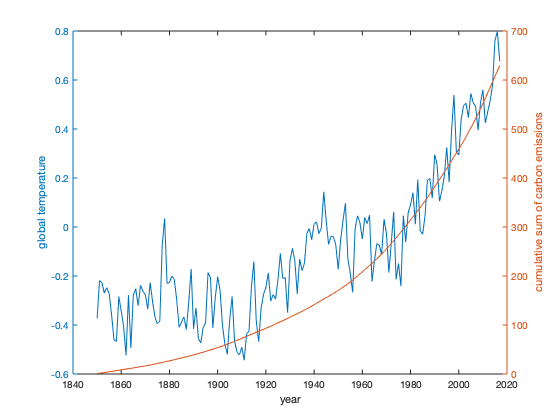

yyaxis right
plot(x, y1c)
ylabel('cumulative sum of carbon emissions')

% initialize a new figure object for the next plot
figure
y2t = T31{:,"Q34"}

y2t =    -0.3730
   -0.2180
   -0.2280
   -0.2690
   -0.2480
   -0.2720
   -0.3580
   -0.4610
   -0.4670
   -0.2840


% define errorbar data 
e2tnegative = T31{:, "Q35"}

e2tnegative =    -0.5910
   -0.4290
   -0.4340
   -0.4720
   -0.4350
   -0.4550
   -0.5410
   -0.6360
   -0.6440
   -0.4700


e2tpositive = T31{:,"Q36"}

e2tpositive =    -0.1620
   -0.0160
   -0.0300
   -0.0750
   -0.0720
   -0.0990
   -0.1820
   -0.2940
   -0.2950
   -0.1060



yyaxis left 
errorbar(x, y2t, e2tnegative, e2tpositive)
xlabel('year')
ylabel('global temperature')
y2c = T31{:,"Q33"}

y2c =     0.7418
    1.4876
    2.2413
    3.0022
    3.7759
    4.5536
    5.3403
    6.1347
    6.9356
    7.7444


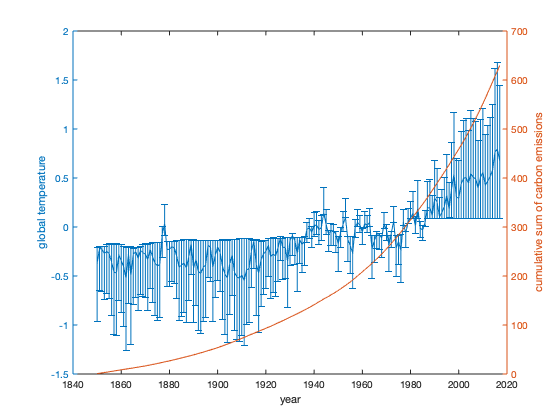

yyaxis right
plot(x, y2c)
ylabel('cumulative sum of carbon emissions')

figure
x = T31{:, "Q33"}

x =     0.7418
    1.4876
    2.2413
    3.0022
    3.7759
    4.5536
    5.3403
    6.1347
    6.9356
    7.7444


y = T31{:, "Q34"}

y =    -0.3730
   -0.2180
   -0.2280
   -0.2690
   -0.2480
   -0.2720
   -0.3580
   -0.4610
   -0.4670
   -0.2840


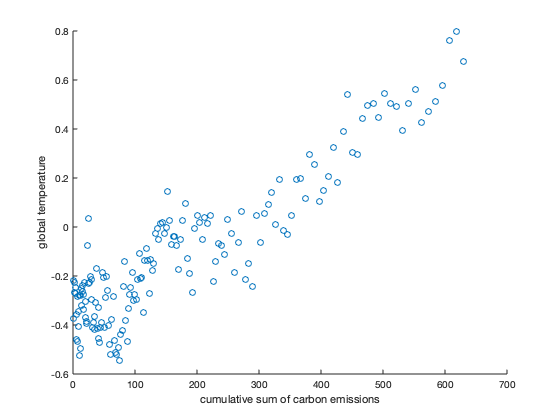

scatter(x, y)
xlabel('cumulative sum of carbon emissions')
ylabel('global temperature')